# 2次元の行列式(1)

ワークスペース変数を消去，コマンドウィンドウを初期化，すべてのFigureウィンドウを閉じる．

clear;clc;close all;
sympref('MatrixWithSquareBrackets',true);

A=[6 2;1 4];
sym(A)

$$ans = \left[\begin{array}{cc} 6 & 2\\ 1 & 4 \end{array}\right]$$

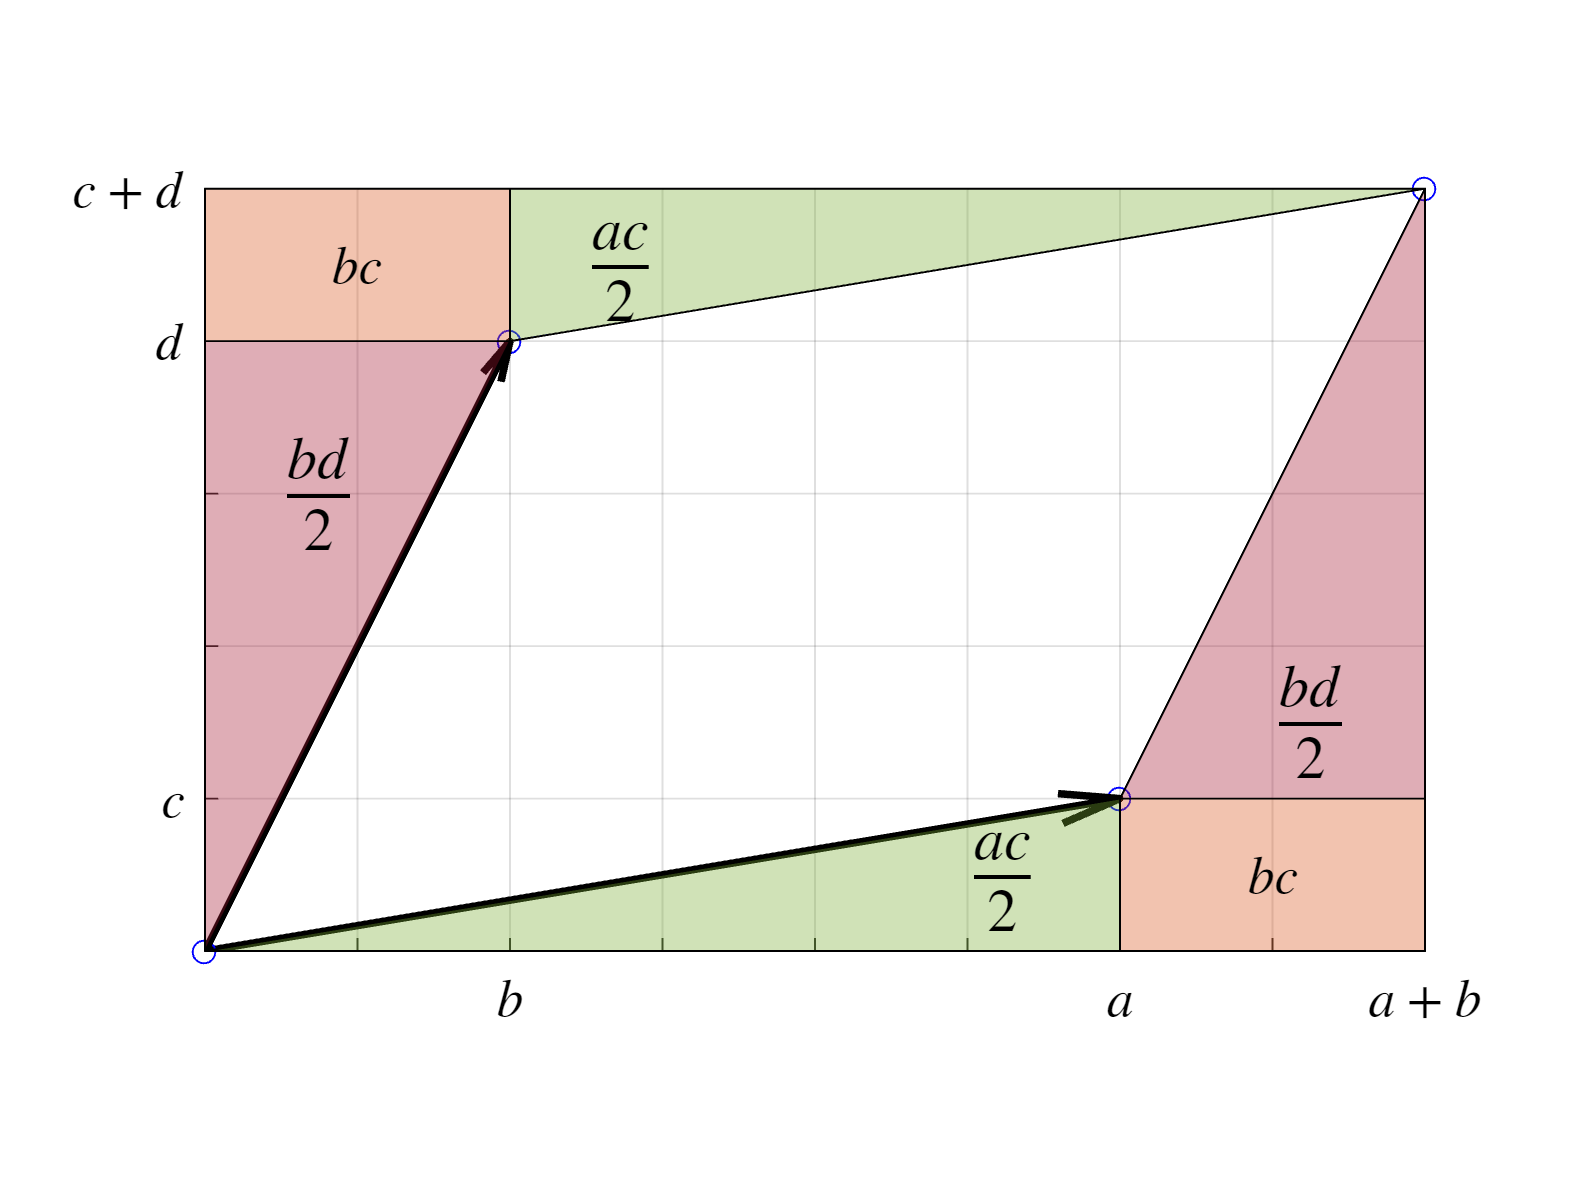

a=A(1,1);b=A(1,2);c=A(2,1);d=A(2,2);

figure
set(gca,'fontname','メイリオ')
hold on;grid on;
plot([0 a a+b],[0 c c+d],'bo-');
quiver(0,0,a,c,'k-','autoscale','off','linewidth',2);
plot([0 b a+b],[0 d c+d],'bo-');
quiver(0,0,b,d,'k-','autoscale','off','linewidth',2);

axis equal;
axis([0 8 0 5])
xticklabels([])
text(a,-0.1,'$a$','Interpreter','latex','FontSize',14,...
    'HorizontalAlignment','center','VerticalAlignment','top')
text(b,-0.1,'$b$','Interpreter','latex','FontSize',14,...
    'HorizontalAlignment','center','VerticalAlignment','top')
text(a+b,-0.1,'$a+b$','Interpreter','latex','FontSize',14,...
    'HorizontalAlignment','center','VerticalAlignment','top')
yticklabels([])
text(-0.1,c,'$c$','Interpreter','latex','FontSize',14,...
    'HorizontalAlignment','right','VerticalAlignment','middle')
text(-0.1,d,'$d$','Interpreter','latex','FontSize',14,...
    'HorizontalAlignment','right','VerticalAlignment','middle')
text(-0.1,c+d,'$c+d$','Interpreter','latex','FontSize',14,...
    'HorizontalAlignment','right','VerticalAlignment','middle')

h_ac=plot(polyshape([0 a a 0],[0 0 c 0]));
plot(polyshape([b a+b b b],[d c+d c+d d]),'FaceColor',h_ac.FaceColor);
text(a/2+2,c/2,'$\frac{ac}{2}$','Interpreter','latex','FontSize',16)
text(b+a/2-2.5,d+c/2,'$\frac{ac}{2}$','Interpreter','latex','FontSize',16)

h_bd=plot(polyshape([0 b 0 0],[0 d d 0]));
plot(polyshape([a a+b a+b a],[c c c+d c]),'FaceColor',h_bd.FaceColor);
text(b/2-0.5,d/2+1,'$\frac{bd}{2}$','Interpreter','latex','FontSize',16)
text(a+b-b/2,d/2-0.5,'$\frac{bd}{2}$','Interpreter','latex','FontSize',16)

h_bc=plot(polyshape([a a+b a+b a],[0 0 c c]));
plot(polyshape([0 b b 0],[d d c+d c+d]),'FaceColor', h_bc.FaceColor);
text(a+b/2,c/2,'$bc$','Interpreter','latex','FontSize',14,'HorizontalAlignment','center');
text(b/2,c/2+d,'$bc$','Interpreter','latex','FontSize',14,'HorizontalAlignment','center');
exportgraphics(gcf,'fig_matrixDeterminantSample01.pdf')

syms a b c d;
simplify((a+b)*(c+d)-a*c-b*d-2*b*c)

$$ans = a\,d-b\,c$$